[Defining An Ultrasound Transducer](https://www.k-wave.org/documentation/example_us_defining_transducer.php)

En principio, la mayoria de simulaciones usando transductores con ultrasonido pueden ser eealizados siguiendo los ejemplo de  [Time Varying Source Problems](https://www.k-wave.org/documentation/k-wave_time_varying_source_problems.php). Sin embargo, asignar los puntos que corresponden al elemento de transductor y lo que conlleva es muy tardado.

Por esta razon, existe **kWaveTransducer** class que puede sustituir la fuente o el sensor o ambos. Para este ejemplo mostraremos como se realiza lo siguiente mediante un campo producido por un trasnductor de ultrasonido.

Los inputs de trasnductor solo pueden usarse en simulaciones 3D, y gastan mucha memora y cpu. Para reducir el gasto computacional, los calculos usan double (8 bytes), sin embargo mejor usaremos single (4 bytes), para ello hacemos: (`'DataCast','single').`

if you have access to a recent model GPU and the MATLAB Parallel Computing Toolbox R2012a or later, the simulation times can be significantly reduced by setting `'DataCast'` to `'gpuArray-single'`

#### **Definimos la senal de entrada**

Primero definimos la senal que sera usada y luego el transductor en ese orden.

Dependiendo del angulo y distancia de enfoque del transductor los **retardos de beamforming **se calculan automaticamente en k-wave.

clear all
%sin steering:
%E1  E2  E3  E4  E5
% \   \  |  /   /
%      foco

%con steering:
%E1  E2  E3  E4  E5
%      \   \   \   \
%            ↘ haz

Note, the properties of the input signal are dependent on the time step used in the simulation, so `kgrid.t_array` must be defined before creating the input signal.

Para crear la senal usamos **toneBurst**: This creates a single frequency sinusoid with a given number of cycles windowed by a Gaussian. 

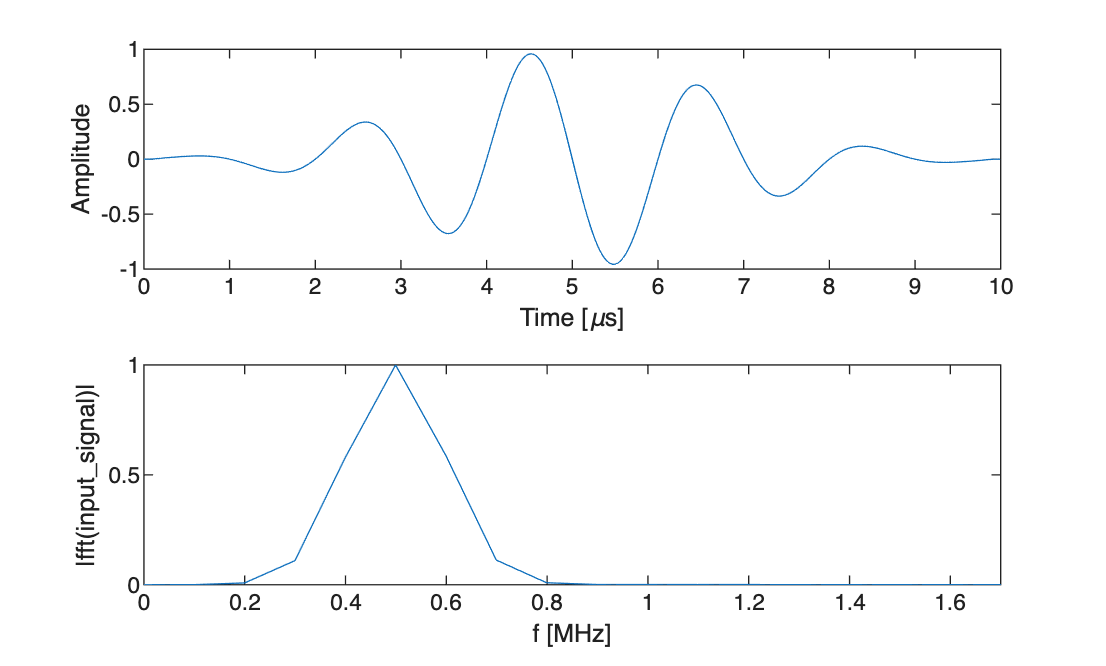

%Defino espacio y tiempo de simulacion
% crear grid 3D (porque el transductor es tridimensional)
Nx = 128;
Ny = 128;
Nz = 64;

dx = 0.1e-3;
dy = 0.1e-3;
dz = 0.1e-3;

kgrid = kWaveGrid(Nx,dx,Ny,dy,Nz,dz);

% definir medio
medium.sound_speed = 1540;   % [m/s]
medium.density = 1000;       % [kg/m^3]

% definir el tiempo de simulacion
kgrid.t_array = makeTime(kgrid,medium.sound_speed);


%---------- Nuevo--------------
% define properties of the input signal
source_strength = 1e6;          % [MPa]
tone_burst_freq = 0.5e6;        % [Hz]
tone_burst_cycles = 5; 

%T= 10 us=1e-5 s 
% Necesito kgrid.dt antes para construir el input signal, entonces
% por eso debo definir el timepo de simulacion antes.
input_signal = toneBurst(1/kgrid.dt, tone_burst_freq, tone_burst_cycles);
t = (0:length(input_signal)-1)*kgrid.dt;

%Ploto el pulso que estoy mandando de 5 ciclos 
% señal temporal
t = (0:length(input_signal)-1)*kgrid.dt;

figure;

subplot(2,1,1);
plot(t*1e6,input_signal);
xlabel('Time [\mus]');
ylabel('Amplitude');

Y = fft(input_signal);
Y_abs = Y/max(Y);

L = length(input_signal);
Fs = 1/kgrid.dt;

subplot(2,1,2);
plot(Fs/L*(0:L-1)*1e-6,abs(Y_abs));
xlabel('f [MHz]');
ylabel('|fft(input\_signal)|');
xlim([0 1.7]);

#### **Definimos el transductor**

This is accomplished by creating an object of the [`kWaveTransducer`](https://www.k-wave.org/documentation/kWaveTransducer.php) class.

First, the physical properties of the transducer are defined, including the number of elements and their size. The sizes are all given in units of grid points which means the physical size is also dependent on the values of `kgrid.dx`, `kgrid.dy`, and `kgrid.dz`.

The `radius` input will be used in future versions of k-Wave to create curved transducers. Solo esta el transductor lineal soportado por el momento.

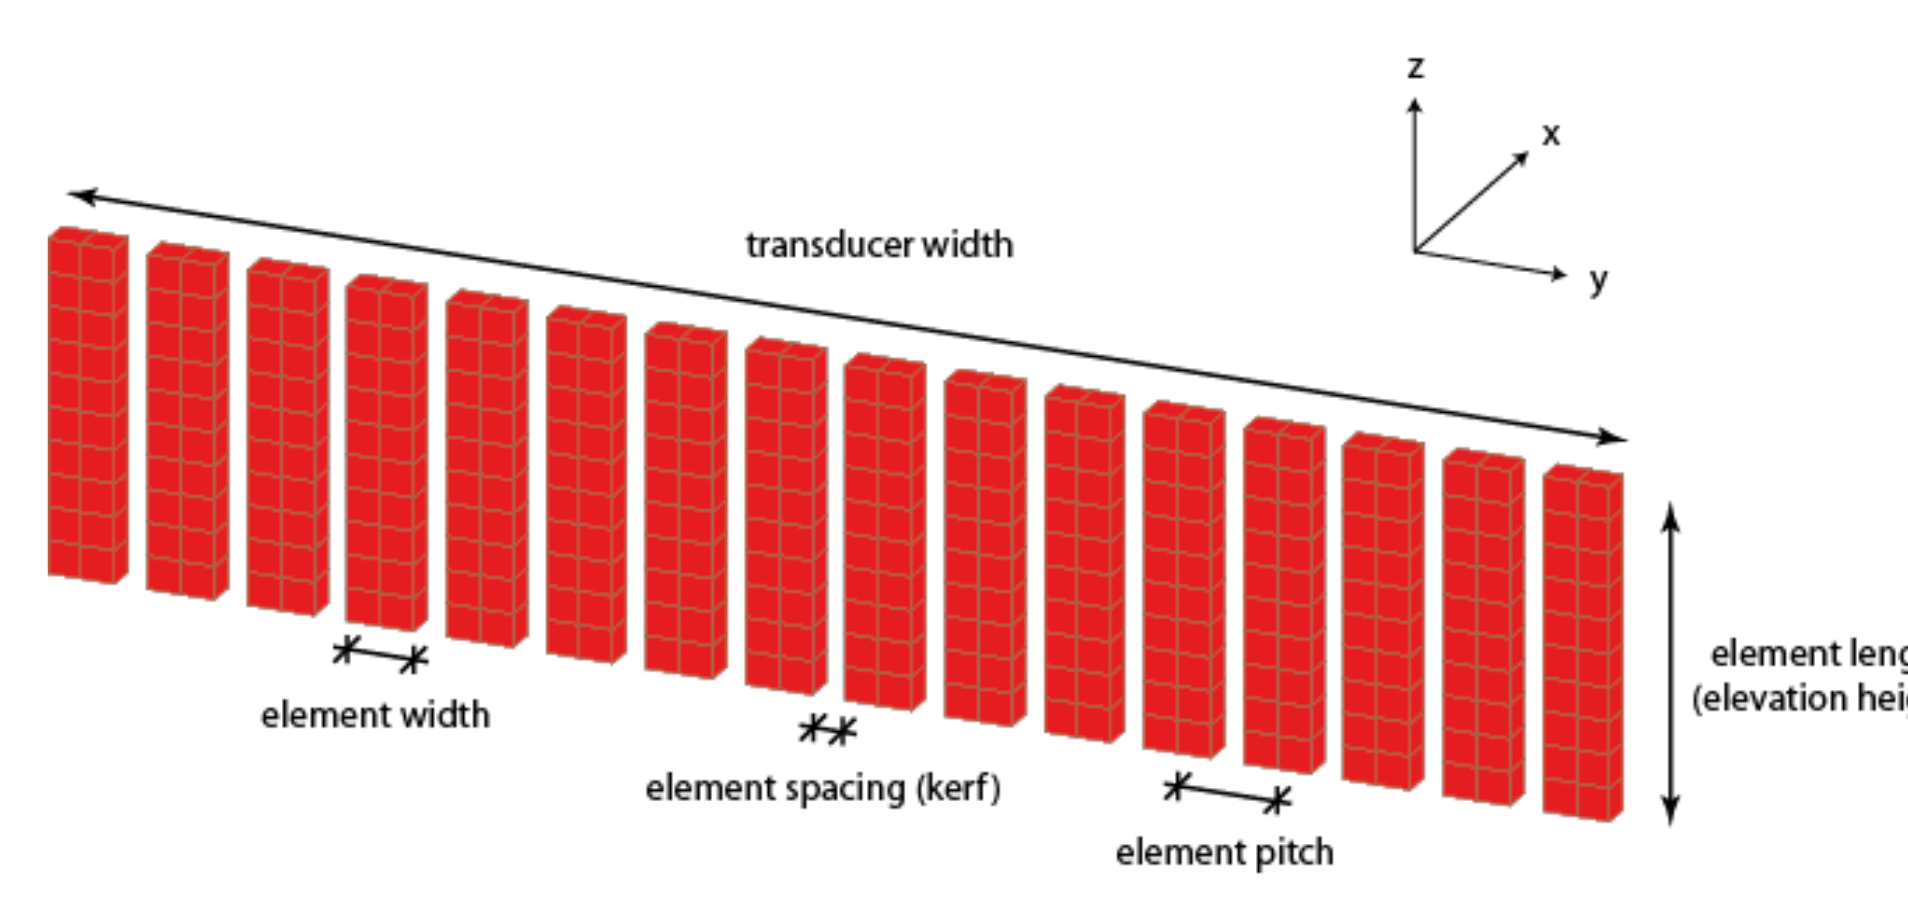

% physical properties of the transducer
transducer.number_elements = 72;    % total number of transducer elements
transducer.element_width = 1;       % width of each element [grid points]
transducer.element_length = 12;     % length of each element [grid points]
transducer.element_spacing = 0;     % spacing (kerf width) between the elements [grid points]
transducer.radius = inf;            % radius of curvature of the transducer [m]

% calculate the width of the transducer in grid points
transducer_width = transducer.number_elements * transducer.element_width ...
    + (transducer.number_elements - 1) * transducer.element_spacing;

% use this to position the transducer in the middle of the computational grid
transducer.position = round([1, Ny/2 - transducer_width/2, Nz/2 - transducer.element_length/2]);


Next, the dynamic properties of the transducer are defined. k-Wave calcula **dos tipos de retardos de beamforming, **sound speed + focus distance + steering angle, 

% properties used to derive the beamforming delays
transducer.sound_speed = 1540;                  % sound speed [m/s]
transducer.focus_distance = 20e-3;              % focus distance [m]
transducer.elevation_focus_distance = 19e-3;    % focus distance in the elevation plane [m]
transducer.steering_angle = 0;                  % steering angle [degrees]

**Apodization:** controla el **peso/amplitud relativa** aplicada a cada elemento activo del transductor.

- con una ventana de `getWin` (por ejemplo `'Hanning'`, `'Hamming'`, etc.),

- con un vector manual de pesos, 

- o dejarse sin definir, en cuyo caso usa `'Rectangular'` por defecto.

% apodization
transducer.transmit_apodization = 'Rectangular';    
transducer.receive_apodization = 'Rectangular';

%Un transductor puede tener muchos elementos físicos, 
% pero no necesariamente todos se usan al mismo tiempo

% define the transducer elements that are currently active
transducer.active_elements = zeros(transducer.number_elements, 1);
transducer.active_elements(21:52) = 1;

% La señal que genere con toneBurst se asigna al transductor:
transducer.input_signal = input_signal;

Antes de esta línea, `transducer` es solo una estructura con parámetros. Después pasa a ser un objeto `kWaveTransducer`, con propiedades y métodos adicionales.

% create the transducer using the defined settings
transducer = kWaveTransducer(kgrid, transducer);

%Para revisar las propieades del transductor
transducer.properties

 
k-Wave Transducer Properties
  transducer position:       [1  28  26]
  transducer width:          7.2mm (72 grid points)
  number of elements:        72
  number of active elements: 32 (elements 21 to 52)
  element width:             100um (1 grid points)
  element spacing (kerf):    0m (0 grid points)
  element pitch:             100um (1 grid points)
  element length:            1.2mm (12 grid points)
  sound speed:               1540m/s
  focus distance:            20mm
  elevation focus distance:  19mm
  steering angle:            0 degrees
  steering angle max:        auto degrees


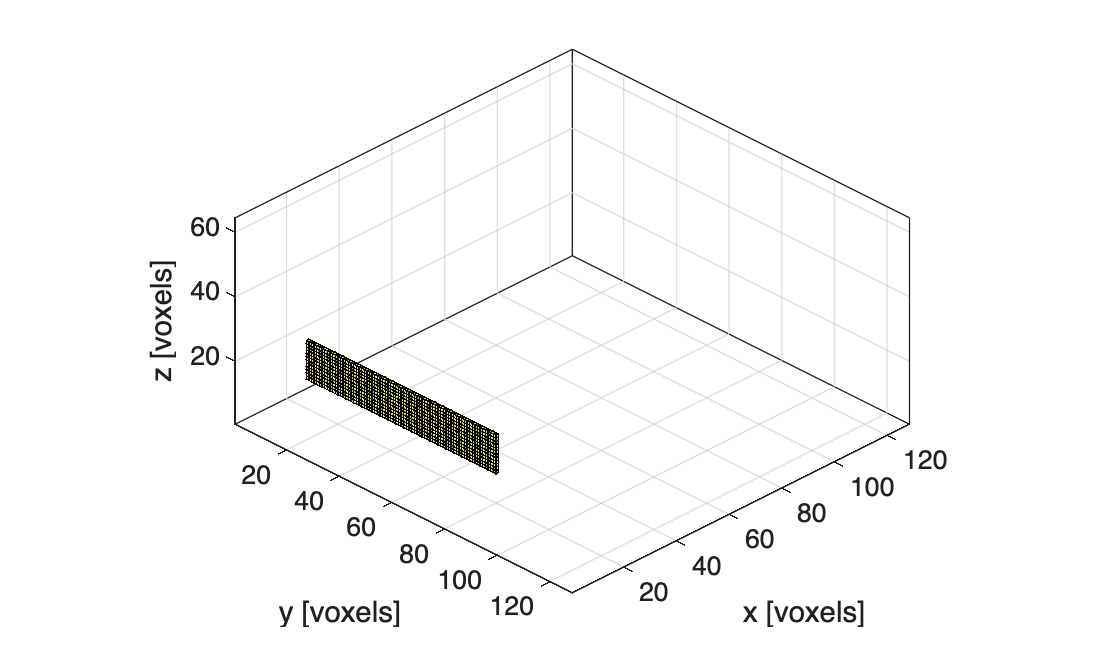

%Para plotear el transductor en el espacio tridimensional
transducer.plot

Ahora para correr la simulacion usaremos kspaceFirstOrder3D, aqui por ejemplo el transductor reempalza source input, pero aun no sensor (aplicaremos una binary mask para eso)

%Para medir en puntos concretos y ver como llega la onda en esos
sensor.mask = zeros(Nx,Ny,Nz);

%3 sensores en puntos concretos
sensor.mask(50,64,32) = 1;
sensor.mask(70,64,32) = 1;
sensor.mask(90,64,32) = 1;

`BonA` controla la **no linealidad acústica**. Al definirlo, k-Wave ya no simula solo propagación lineal, sino que incluye la distorsión no lineal de la onda.

% run the simulation
%smooth solo genera inconvenientes cuando se usa ene source
[sensor_data]= kspaceFirstOrder3D(kgrid, medium, transducer, sensor);

Running k-Wave simulation...
  start time: 31-Aug-2026 10:05:38
  reference sound speed: 1540m/s
  prepending transducer.input_signal with 2 leading zeros
  appending transducer.input_signal with 2 trailing zeros
  dt: 19.4805ns, t_end: 12.4675us, time steps: 641
  input grid size: 128 by 128 by 64 grid points (12.8 by 12.8 by 6.4mm)
  maximum supported frequency: 7.7MHz
  precomputation completed in 0.64044s
  starting time loop...
  estimated simulation time 28.728s...
  simulation completed in 24.4442s
  total computation time 25.1308s


**1. Dominio temporal:** `sensor_data` muestra cómo cambia la presión con el tiempo en cada sensor. Al propagarse una onda de amplitud alta por un medio no lineal, la forma del pulso puede ir deformándose.

**2. Dominio de frecuencia:** al aplicar FFT a cada señal registrada, observas qué frecuencias contiene. 

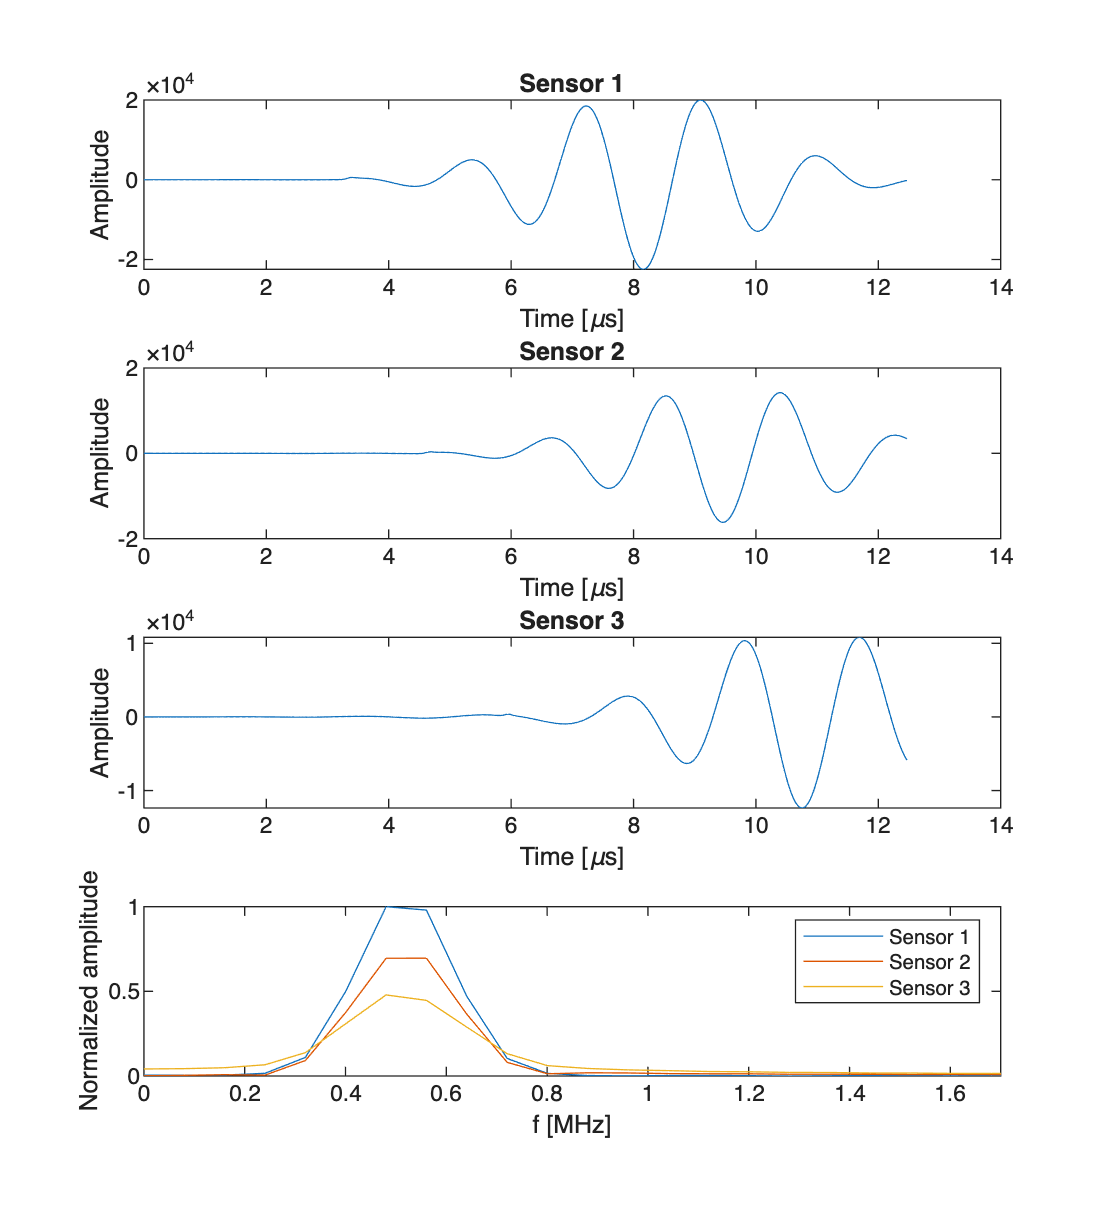

t = kgrid.t_array;

figure('Position',[100 100 900 1000]);
%temporal
subplot(4,1,1);
plot(t*1e6,sensor_data(1,:));
xlabel('Time [\mus]');
ylabel('Amplitude');
title('Sensor 1');

subplot(4,1,2);
plot(t*1e6,sensor_data(2,:));
xlabel('Time [\mus]');
ylabel('Amplitude');
title('Sensor 2');

subplot(4,1,3);
plot(t*1e6,sensor_data(3,:));
xlabel('Time [\mus]');
ylabel('Amplitude');
title('Sensor 3');

%Espectral
Y1 = fft(sensor_data(1,:));
Y2 = fft(sensor_data(2,:));
Y3 = fft(sensor_data(3,:));

L = size(sensor_data,2);
Fs = 1/kgrid.dt;

Y1_abs = abs(Y1)/max(abs(Y1));
Y2_abs = abs(Y2)/max(abs(Y1));
Y3_abs = abs(Y3)/max(abs(Y1));

subplot(4,1,4);
plot(Fs/L*(0:L-1)*1e-6,Y1_abs);
hold on;
plot(Fs/L*(0:L-1)*1e-6,Y2_abs);
plot(Fs/L*(0:L-1) *1e-6,Y3_abs);

xlabel('f [MHz]');
ylabel('Normalized amplitude');
legend('Sensor 1','Sensor 2','Sensor 3');
xlim([0 1.7]);

Al definir** 3 sensores a distintas profundidades: **cuanto mayor es la profundidad del sensor, mayor es el tiempo de llegada, por ello la onda va perdiendo amplitud conforme se propaga a mas distancia recorrida se puede observar una mayor atenuacion. Asimismo el transductor está **focalizado, **por lo que depende tambien si cada sensor está antes, cerca o después del foco. El haz se concentra hacia la región focal y luego vuelve a divergir.

[Simulating Ultrasound Beam Patterns](https://www.k-wave.org/documentation/example_us_beam_patterns.php)

Una vez se genera el transductor, un mapa de los resultados de presion peude ser generado a partir de elegir un plano, convertirlo en sensores y guardar ahi solo las metricas de presion (*beam pattern)*:

clear transducer sensor sensor_data

%% Especifico el tamano del PML
PML_X_SIZE = 20;
PML_Y_SIZE = 10;
PML_Z_SIZE = 10;

%% K grid de la malla
Nx = 128 - 2*PML_X_SIZE;
Ny = 256 - 2*PML_Y_SIZE;
Nz = 64  - 2*PML_Z_SIZE;

x = 40e-3;

dx = x/Nx;
dy = dx;
dz = dx;

kgrid = kWaveGrid(Nx,dx,Ny,dy,Nz,dz);

%% medio
medium.sound_speed = 1540;
medium.density = 1000;
medium.alpha_coeff = 0.75;
medium.alpha_power = 1.5;
medium.BonA = 6; %no linearidad

%% tiempo
t_end = 45e-6;
kgrid.t_array = makeTime(kgrid,medium.sound_speed,[],t_end);

%% input signal
source_strength = 1e6;
tone_burst_freq = 0.5e6;
tone_burst_cycles = 5;

input_signal = toneBurst( ...
    1/kgrid.dt,...
    tone_burst_freq,...
    tone_burst_cycles);

input_signal = ...
    (source_strength/(medium.sound_speed*medium.density)) ...
    .* input_signal;

%% transductor
transducer.number_elements = 32;
transducer.element_width = 1;
transducer.element_length = 12;
transducer.element_spacing = 0;
transducer.radius = inf;

transducer_width = ...
    transducer.number_elements*transducer.element_width ...
    + (transducer.number_elements-1)*transducer.element_spacing;

transducer.position = round([ ...
    1,...
    Ny/2-transducer_width/2,...
    Nz/2-transducer.element_length/2]);

transducer.sound_speed = 1540;
transducer.focus_distance = 20e-3;
transducer.elevation_focus_distance = 19e-3;
transducer.steering_angle = 0;

transducer.transmit_apodization = 'Rectangular';
transducer.receive_apodization = 'Rectangular';

transducer.active_elements = ones(32,1);
transducer.input_signal = input_signal;

transducer = kWaveTransducer(kgrid,transducer);

%% SENSOR: CENTRAL X-Y PLANE
sensor.mask = zeros(Nx,Ny,Nz);
sensor.mask(:,:,Nz/2) = 1;

sensor.record = {'p_rms','p_max'};

%% SIMULATION
input_args = { ...
    'PMLInside',false,...
    'PMLSize',[PML_X_SIZE,PML_Y_SIZE,PML_Z_SIZE],...
    'PlotPML',false,...
    'DataCast','single',...
    'DataRecast',true};

sensor_data = kspaceFirstOrder3D( ...
    kgrid,medium,transducer,sensor,input_args{:});

Running k-Wave simulation...
  start time: 31-Aug-2026 10:06:04
  reference sound speed: 1540m/s
  prepending transducer.input_signal with 10 leading zeros
  appending transducer.input_signal with 10 trailing zeros
  dt: 88.5478ns, t_end: 44.9823us, time steps: 509
  input grid size: 88 by 236 by 44 grid points (40 by 107.2727 by 20mm)
  maximum supported frequency: 1.694MHz
  expanding computational grid...
  computational grid size: 128 by 256 by 64 grid points
  casting variables to single type...
  precomputation completed in 0.37317s
  starting time loop...
  estimated simulation time 43.3315s...
  simulation completed in 43.3992s
  recasting variables to double...
  total computation time 43.8092s


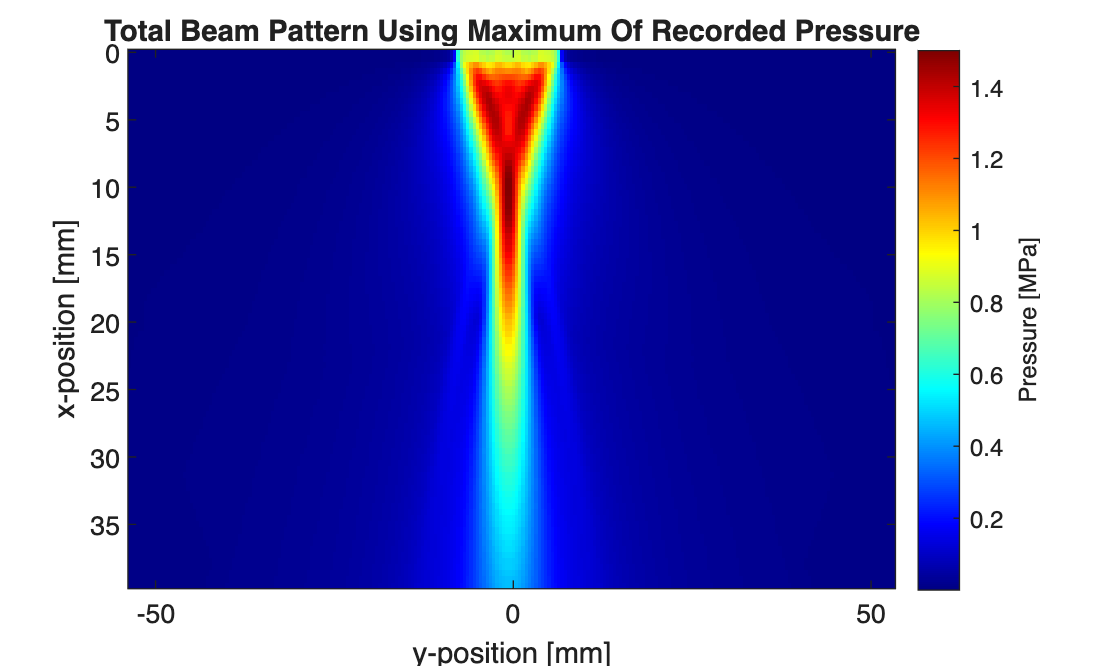


%% RESHAPE
sensor_data.p_rms = reshape(sensor_data.p_rms,[Nx,Ny]);
sensor_data.p_max = reshape(sensor_data.p_max,[Nx,Ny]);

%% PLOT
figure;

imagesc( ...
    kgrid.y_vec*1e3,...
    (kgrid.x_vec-min(kgrid.x_vec(:)))*1e3,...
    sensor_data.p_max*1e-6);

xlabel('y-position [mm]');
ylabel('x-position [mm]');
title('Total Beam Pattern Using Maximum Of Recorded Pressure');

colormap(jet(256));

c = colorbar;
ylabel(c,'Pressure [MPa]');

**Interpretación del beam pattern:** el mapa `p_max` representa la máxima presión alcanzada en cada punto del plano x-y durante toda la simulación. El haz se propaga en dirección +x, permanece centrado en y = 0 debido a un steering angle de 0°, converge hacia la distancia focal programada (~20 mm), donde presenta su menor ancho y mayor concentración energética, y posteriormente diverge mientras disminuye la presión. 

Asimismo,al inicio hize 3 iteraciones que estaban mal pues el transductor estaba practicamente en el PML generando imagenes incoherentes, ya que la PML evita reflexiones artificiales en los límites computacionales. `PMLInside=false` no elimina la PML; la coloca fuera de la malla definida, permitiendo usar todo el dominio como región física y evitando que un transductor situado en el borde quede dentro de la zona absorbente.

En resumen:

`PMLInside=true`: la PML ocupa parte de la malla definida. `PMLInside``=false`: toda la malla definida se considera dominio físico y k-Wave añade la PML alrededor de ella.

[Example: Using An Ultrasound Transducer As A Sensor](https://www.k-wave.org/documentation/example_us_transducer_as_sensor.php)

This example shows how an ultrasound transducer can be used as a detector by substituting a transducer object for the normal `sensor` input structure.

clear;
clc;
close all;

%% =========================================================
% 1. PARAMETERS
% ==========================================================

PML_SIZE = 10;

Nx = 128;
Ny = 128;
Nz = 64;

dx = 0.2e-3;
dy = 0.2e-3;
dz = 0.2e-3;

c0   = 1540;      % [m/s]
rho0 = 1000;      % [kg/m^3]

source_strength = 1e6;   % [Pa]

%% =========================================================
% 2. GRID
% ==========================================================

kgrid = kWaveGrid( ...
    Nx, dx, ...
    Ny, dy, ...
    Nz, dz);

%% =========================================================
% 3. MEDIUM
% ==========================================================

% Definir todo como matrices 3D para evitar incompatibilidades
medium.sound_speed = c0 .* ones(Nx, Ny, Nz);
medium.density     = rho0 .* ones(Nx, Ny, Nz);

medium.alpha_coeff = 0.75 .* ones(Nx, Ny, Nz);
medium.alpha_power = 1.5;

medium.BonA = 6 .* ones(Nx, Ny, Nz);

%% =========================================================
% 4. TIME ARRAY
% ==========================================================

t_end = 30e-6;

kgrid.t_array = makeTime( ...
    kgrid, ...
    medium.sound_speed, ...
    [], ...
    t_end);

%% =========================================================
% 5. INITIAL PRESSURE SOURCES
% ==========================================================

source.p0 = zeros(Nx, Ny, Nz);

% Fuente 1:
% más cercana y fuera del eje
ball_1 = makeBall( ...
    Nx, Ny, Nz, ...
    45, ...
    45, ...
    round(Nz/2), ...
    3);

% Fuente 2:
% más profunda y aproximadamente on-axis
ball_2 = makeBall( ...
    Nx, Ny, Nz, ...
    80, ...
    round(Ny/2), ...
    round(Nz/2), ...
    3);

source.p0(ball_1 == 1) = source_strength;
source.p0(ball_2 == 1) = source_strength;

%% =========================================================
% 6. TRANSDUCER CONFIGURATION
% ==========================================================

transducer_cfg.number_elements = 32;

transducer_cfg.element_width   = 1;     % grid points
transducer_cfg.element_length  = 12;    % grid points
transducer_cfg.element_spacing = 0;     % grid points

transducer_cfg.radius = inf;

%% =========================================================
% 7. TRANSDUCER WIDTH
% ==========================================================

transducer_width = ...
    transducer_cfg.number_elements ...
    * transducer_cfg.element_width ...
    + ...
    (transducer_cfg.number_elements - 1) ...
    * transducer_cfg.element_spacing;

%% =========================================================
% 8. TRANSDUCER POSITION
% ==========================================================

% PMLInside = true
% Por eso lo colocamos después del PML interno

transducer_cfg.position = round([ ...
    PML_SIZE + 1, ...
    Ny/2 - transducer_width/2, ...
    Nz/2 - transducer_cfg.element_length/2]);

%% =========================================================
% 9. RECEIVE BEAMFORMING SETTINGS
% ==========================================================

transducer_cfg.sound_speed = c0;

transducer_cfg.focus_distance = 20e-3;

transducer_cfg.elevation_focus_distance = 19e-3;

transducer_cfg.steering_angle = 0;

transducer_cfg.transmit_apodization = ...
    'Rectangular';

transducer_cfg.receive_apodization = ...
    'Rectangular';

%% =========================================================
% 10. ACTIVE ELEMENTS
% ==========================================================

transducer_cfg.active_elements = ...
    ones(transducer_cfg.number_elements, 1);

%% =========================================================
% 11. CREATE TRANSDUCER OBJECT
% ==========================================================

transducer = kWaveTransducer( ...
    kgrid, ...
    transducer_cfg);

%% =========================================================
% 12. CHECK DIMENSIONS
% ==========================================================

disp('----- DIMENSION CHECK -----');

----- DIMENSION CHECK -----



disp('source.p0:');

source.p0:


disp(size(source.p0));

   128   128    64




disp('medium.sound_speed:');

medium.sound_speed:


disp(size(medium.sound_speed));

   128   128    64




disp('medium.density:');

medium.density:


disp(size(medium.density));

   128   128    64




disp('Expected:');

Expected:


disp([Nx Ny Nz]);

   128   128    64



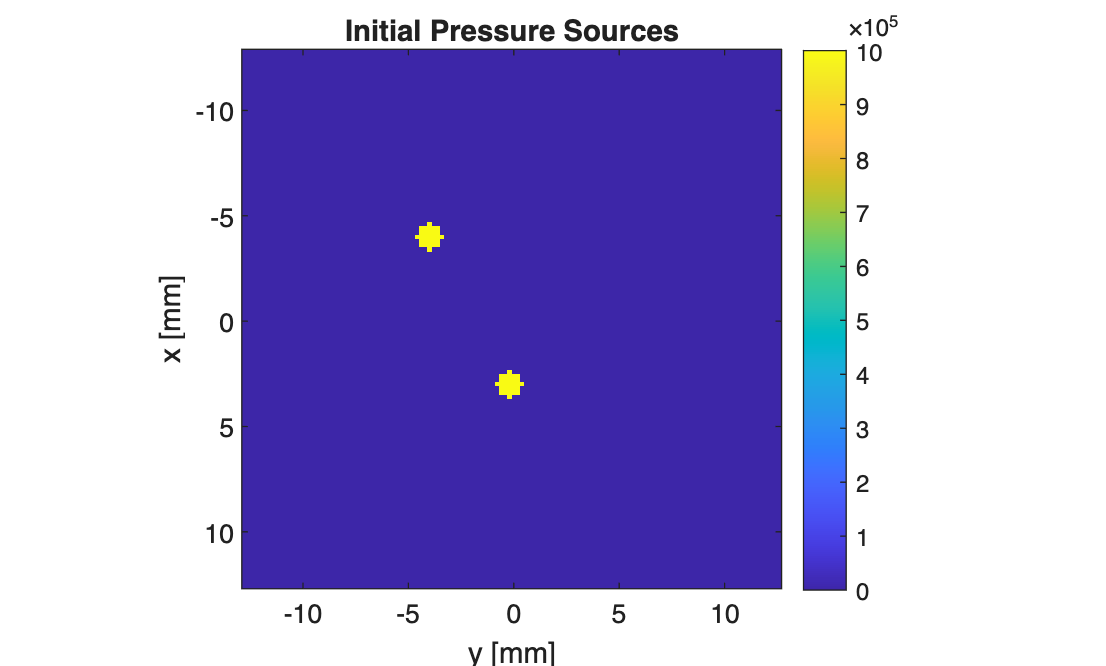


%% =========================================================
% 13. VISUALISE THE TWO SOURCES
% ==========================================================

z_slice = round(Nz/2);

figure;

imagesc( ...
    kgrid.y_vec * 1e3, ...
    kgrid.x_vec * 1e3, ...
    squeeze(source.p0(:,:,z_slice)));

axis image;
colorbar;

xlabel('y [mm]');
ylabel('x [mm]');

title('Initial Pressure Sources');

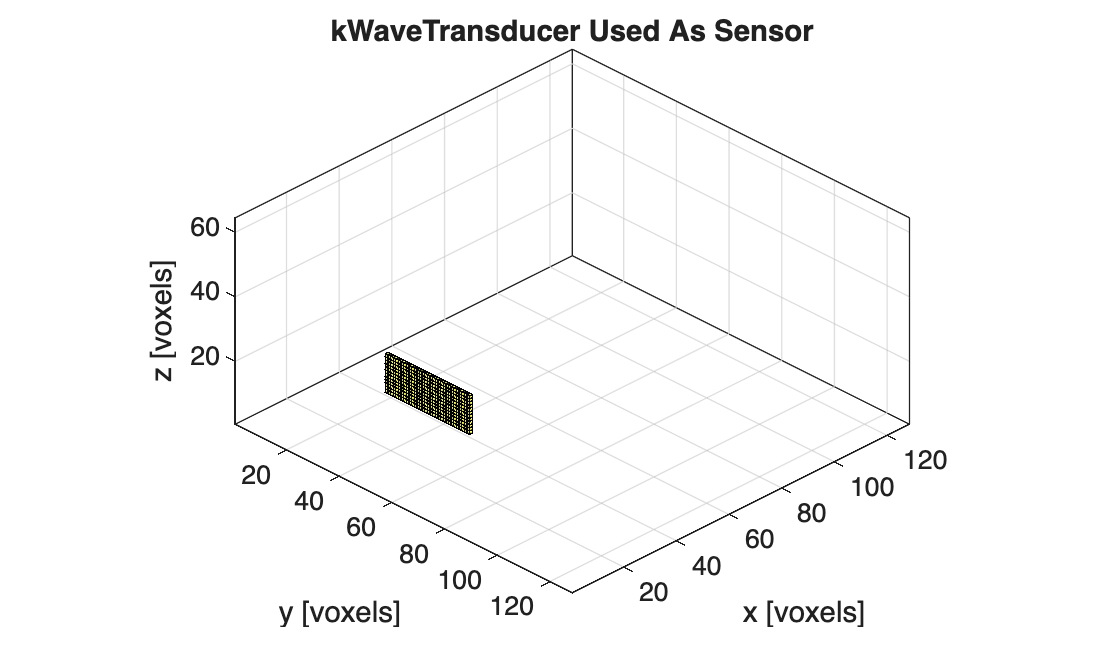


%% =========================================================
% 14. VISUALISE TRANSDUCER
% ==========================================================

figure;

transducer.plot;

title('kWaveTransducer Used As Sensor');


%% =========================================================
% 15. SIMULATION OPTIONS
% ==========================================================

input_args = { ...
    'PMLInside', true, ...
    'PMLSize', [PML_SIZE PML_SIZE PML_SIZE], ...
    'PlotPML', true, ...
    'Smooth', false, ...
    'DataCast', 'single', ...
    'DataRecast', true};

%% =========================================================
% 16. RUN SIMULATION
%
% source      = two pressure sources
% transducer  = sensor
% ==========================================================

sensor_data = kspaceFirstOrder3D( ...
    kgrid, ...
    medium, ...
    source, ...
    transducer, ...
    input_args{:});

Running k-Wave simulation...
  start time: 31-Aug-2026 10:17:04
  reference sound speed: 1540m/s
  dt: 38.961ns, t_end: 30us, time steps: 771
  input grid size: 128 by 128 by 64 grid points (25.6 by 25.6 by 12.8mm)
  maximum supported frequency: 3.85MHz
  casting variables to single type...
  precomputation completed in 0.69014s
  starting time loop...
  estimated simulation time 48.3078s...
  simulation completed in 44.4496s
  recasting variables to double...
  total computation time 45.1875s



%% =========================================================
% 17. CHECK SENSOR DATA
% ==========================================================

disp('----- SENSOR DATA SIZE -----');

----- SENSOR DATA SIZE -----


disp(size(sensor_data));

    32   771



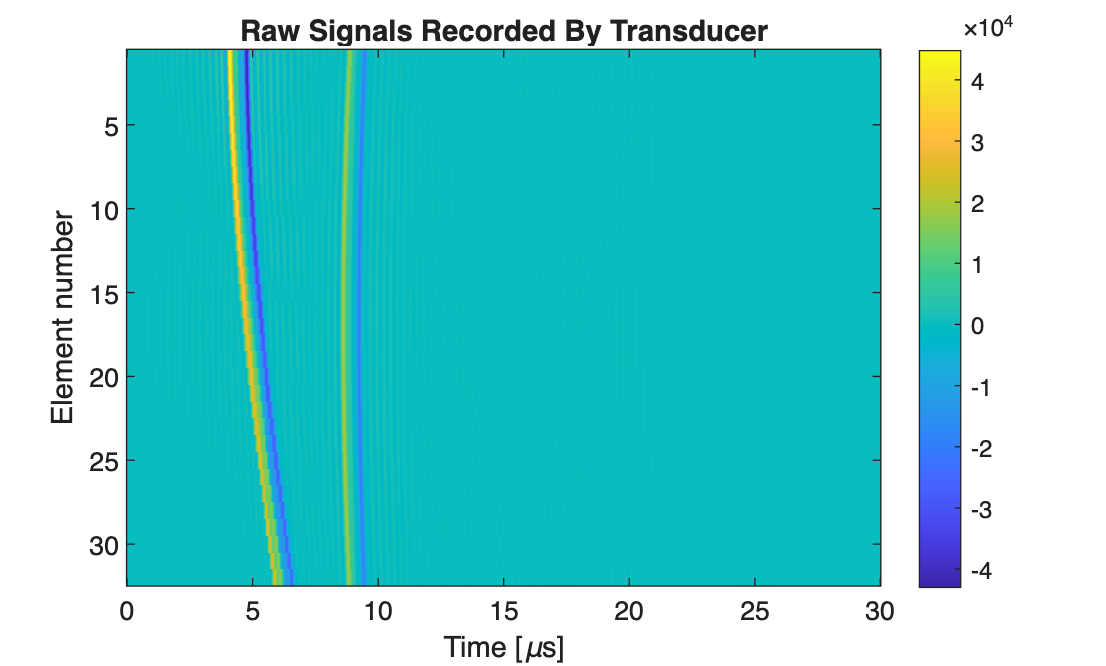


% Esperado:
% [32 x Nt] aproximadamente
%
% sensor_data(element_number, time)

%% =========================================================
% 18. RAW SENSOR DATA - ALL ELEMENTS
% ==========================================================

figure;

imagesc( ...
    kgrid.t_array * 1e6, ...
    1:transducer_cfg.number_elements, ...
    sensor_data);

axis tight;

xlabel('Time [\mus]');
ylabel('Element number');

title('Raw Signals Recorded By Transducer');

colorbar;

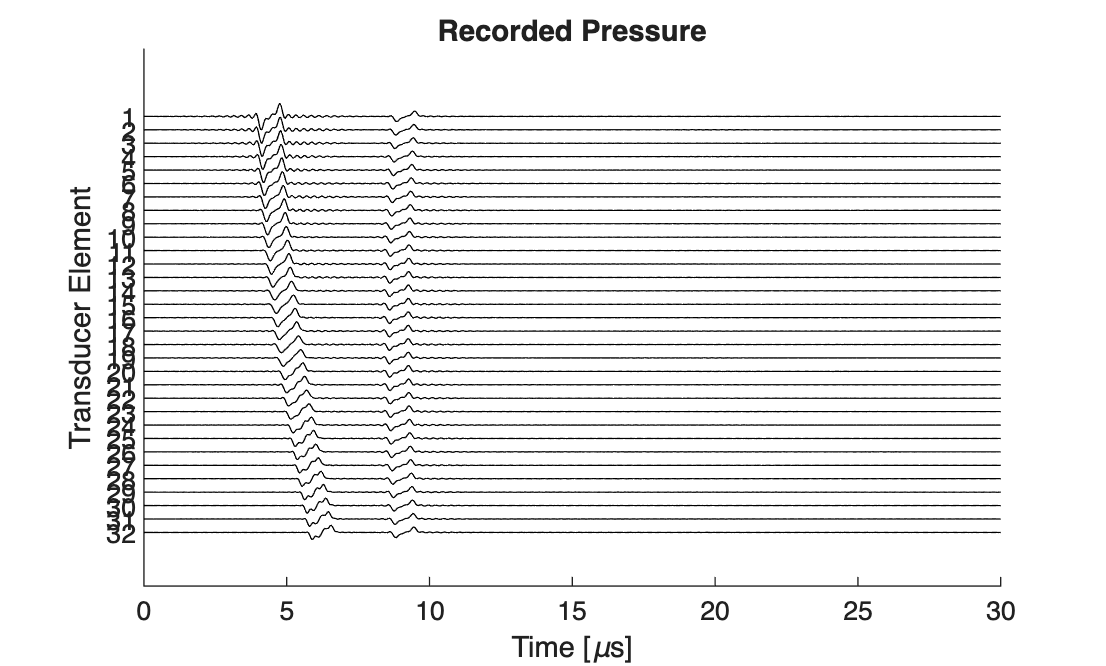

%% =========================================================
% RECORDED PRESSURE - 32 ELEMENTS
% ==========================================================

figure;

% normalizar solo para visualización
sensor_data_norm = sensor_data ./ max(abs(sensor_data(:)));

offset = 1;

hold on;

for elem = 1:size(sensor_data_norm,1)

    plot( ...
        kgrid.t_array * 1e6, ...
        sensor_data_norm(elem,:) + (elem-1)*offset, ...
        'k');

end

set(gca,'YDir','reverse');

xlabel('Time [\mus]');
ylabel('Transducer Element');

title('Recorded Pressure');

yticks(0:offset:(size(sensor_data_norm,1)-1)*offset);
yticklabels(1:size(sensor_data_norm,1));

xlim([0 30]);

grid off;

**RF cruda registrada por cada uno de los 32 elementos del transductor antes del receive beamforming**. Las diferencias en el tiempo de llegada entre elementos contienen información sobre la posición espacial de la fuente. Una fuente off-axis produce un patrón temporal inclinado o curvo entre los canales, mientras que una fuente próxima al eje central genera una distribución más simétrica. Estas señales multicanal son posteriormente alineadas y combinadas mediante receive beamforming para formar una scan line.

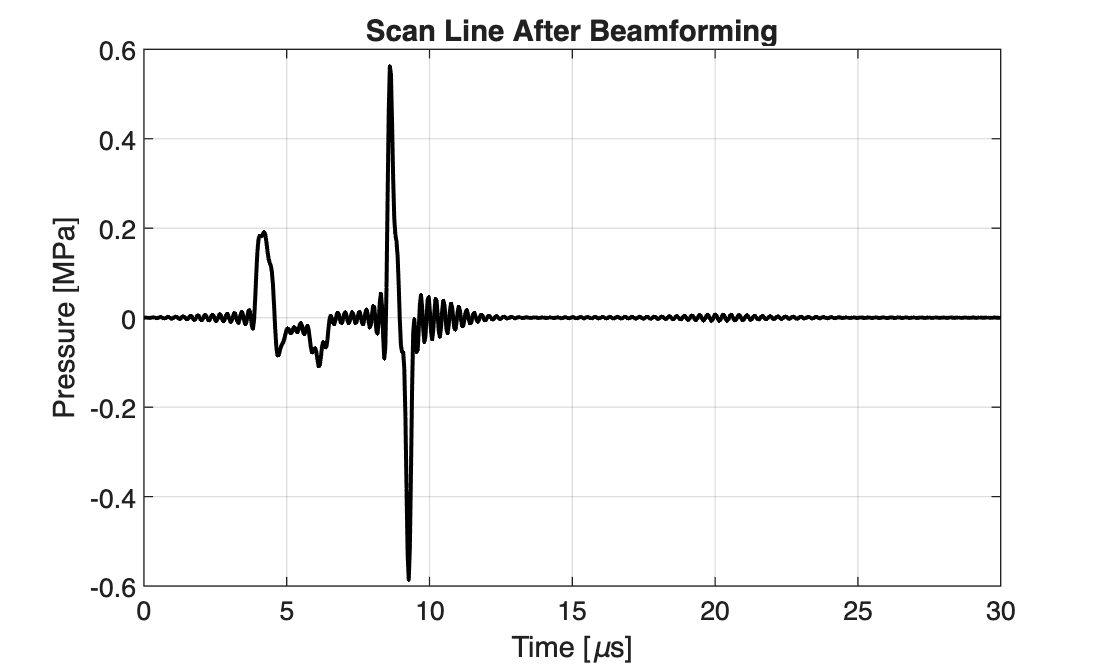

% extract a single scan line from the sensor data using the current
% beamforming settings
scan_line = transducer.scan_line(sensor_data);

figure;

plot( ...
    kgrid.t_array(1:length(scan_line)) * 1e6, ...
    scan_line * 1e-6, ...
    'k', ...
    'LineWidth', 1.5);

xlabel('Time [\mus]');
ylabel('Pressure [MPa]');
title('Scan Line After Beamforming');

grid on;

La scan line representa la señal obtenida después del receive beamforming de los canales registrados por los elementos del transductor. Los picos indican eventos acústicos detectados a diferentes tiempos. Una mayor amplitud después del beamforming indica que las señales de los diferentes elementos se alinearon de forma más coherente para esa dirección/región, produciendo una suma constructiva.

[Example: Simulating B-mode Ultrasound Images](https://www.k-wave.org/documentation/example_us_bmode_linear_transducer.php)

Este ejemplo muestra cómo k-Wave puede generar una **imagen B-mode simulada**, similar a la producida por un ecógrafo diagnóstico moderno.

clear all;
close all;
clc;

Using a modern desktop CPU (with `'DataCast'` set to `'single'`), this increases to around 30 minutes. In this example, the final image is constructed using 96 scan lines. This makes the total computational time around 4.5 hours using a single GPU, or 2 days using a CPU.

Se utilizará un phased array de 64 elementos. Se generarán varias scan lines cambiando el steering angle.

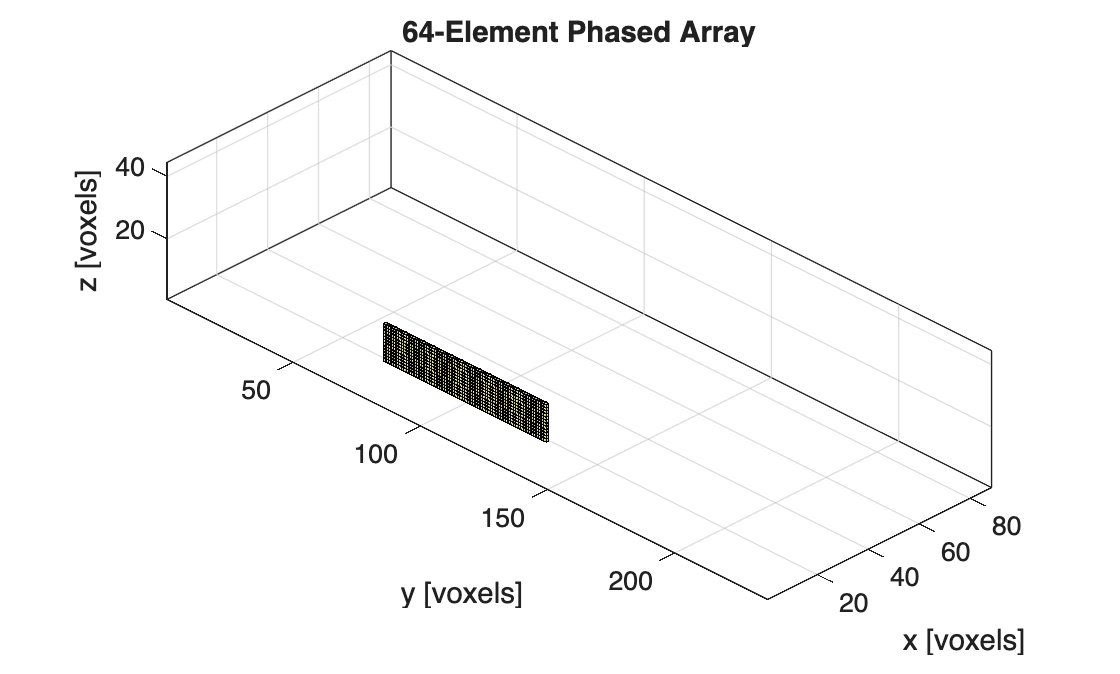

% 1. PARÁMETROS GENERALES
number_elements   = 64;
number_scan_lines = 64;

c0   = 1540;       % velocidad del sonido [m/s]
rho0 = 1000;       % densidad [kg/m^3]

% Ángulos utilizados para barrer el sector
steering_angles = linspace(-20, 20, number_scan_lines);

% PML: Absorbe las ondas que llegan a los límites de la simulación
% para evitar reflexiones artificiales.
PML_X_SIZE = 20;
PML_Y_SIZE = 10;
PML_Z_SIZE = 10;

% 3. KGRID - MALLA COMPUTACIONAL
Nx = 128 - 2*PML_X_SIZE; %profundidad
Ny = 256 - 2*PML_Y_SIZE; %lateral
Nz = 64  - 2*PML_Z_SIZE; %elevacion

% Profundidad física aproximada del dominio
x_size = 40e-3;     % [m]

dx = x_size/Nx;
dy = dx;
dz = dx;

kgrid = kWaveGrid(Nx, dx, Ny, dy, Nz, dz);

% MEDIUM: Define las propiedades acústicas del medio.
medium.sound_speed = c0;%velocidad del sonido
medium.density     = rho0; %densidad
medium.alpha_coeff = 0.75; %absorción
medium.alpha_power = 1.5;%dependencia frecuencial de absorción
medium.BonA = 6;%no linealidad acústica


% TIEMPO DE SIMULACIÓN: Se calcula dt y el número de pasos temporales.
%
% t_end debe permitir que:
%
% transductor -> tejido -> eco -> transductor

t_end = 45e-6;      % [s]

kgrid.t_array = makeTime(kgrid, medium.sound_speed, [], t_end);


%SOURCE: el objeto kWaveTransducer será utilizado directamente
% como source.

% Primero generamos la señal que transmitirá cada elemento.
source_strength   = 1e6;       % presión deseada [Pa]
tone_burst_freq   = 0.5e6;     % frecuencia central [Hz]
tone_burst_cycles = 5;

input_signal = toneBurst(1/kgrid.dt,tone_burst_freq,tone_burst_cycles);

% kWaveTransducer utiliza una fuente de velocidad.
% Por eso convertimos aproximadamente:
%
% p = rho*c*u
% u = p/(rho*c)

input_signal = source_strength/(rho0*c0).* input_signal;

% TRANSDUCTOR: se define un phased array de 64 elementos.

% Todos los elementos permanecen físicamente en el mismo lugar.
% El haz se moverá electrónicamente usando steering_angle.
transducer.number_elements = number_elements;
transducer.element_width   = 1;      % grid points
transducer.element_length  = 12;     % grid points
transducer.element_spacing = 0;      % grid points
transducer.radius = inf;


% Ubicacion del transductor: primero calculamos el ancho total 
% del array para poder centrarlo.
transducer_width = transducer.number_elements* transducer.element_width + (transducer.number_elements - 1) * transducer.element_spacing;

% El transductor queda en el extremo inicial de x
% y centrado en y-z.
transducer.position = round([1, Ny/2 - transducer_width/2, Nz/2 - transducer.element_length/2]);

% BEAMFORMING DEL TRANSDUCTOR: el steering_angle se modificará 
% después dentro del for.
transducer.sound_speed = c0;
transducer.focus_distance = 20e-3; % profundidad focal.
transducer.elevation_focus_distance = 19e-3; % profundidad focal.
transducer.steering_angle = 0;% ángulo al que apunta el haz.


% APODIZACIÓN: Define el peso de cada elemento durante transmisión
%  y recepción.
%
% Rectangular:
% todos los elementos activos tienen el mismo peso.
transducer.transmit_apodization = 'Rectangular';
transducer.receive_apodization = 'Rectangular';

% ELEMENTOS ACTIVOS: Todos los elementos del phased array estarán activos.
transducer.active_elements = ones(number_elements, 1);

% ASIGNAR SOURCE AL TRANSDUCTOR: esta es la señal que utilizará el
%  transductor para transmitir.
transducer.input_signal = input_signal;

%Generamos el transductor
transducer = kWaveTransducer( kgrid, transducer);


%% =========================================================
% 14. VISUALIZAR TRANSDUCTOR
% ==========================================================

figure;
transducer.plot;
title('64-Element Phased Array');

Dura por lo menos 1 hora con mi laptop asi que es mejor computarlo con gpu o solo usando un ejemplo de los RF para evitarnos el proceso.

Running k-Wave simulation...
  start time: 31-Aug-2026 12:48:25
  reference sound speed: 1540m/s
  prepending transducer.input_signal with 71 leading zeros
  appending transducer.input_signal with 71 trailing zeros
  dt: 88.5478ns, t_end: 44.9823us, time steps: 509
  input grid size: 88 by 236 by 44 grid points (40 by 107.2727 by 20mm)
  maximum supported frequency: 1.694MHz
  expanding computational grid...
  computational grid size: 128 by 256 by 64 grid points
  casting variables to single type...
  precomputation completed in 0.58804s
  starting time loop...
  estimated simulation time 44.2216s...
  simulation completed in 48.5412s
  recasting variables to double...
  total computation time 49.261s
Running k-Wave simulation...
  start time: 31-Aug-2026 12:49:15
  reference sound speed: 1540m/s
  prepending transducer.input_signal with 69 leading zeros
  appending transducer.input_signal with 69 trailing zeros
  dt: 88.5478ns, t_end: 44.9823us, time steps: 509
  input grid size: 88 

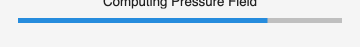

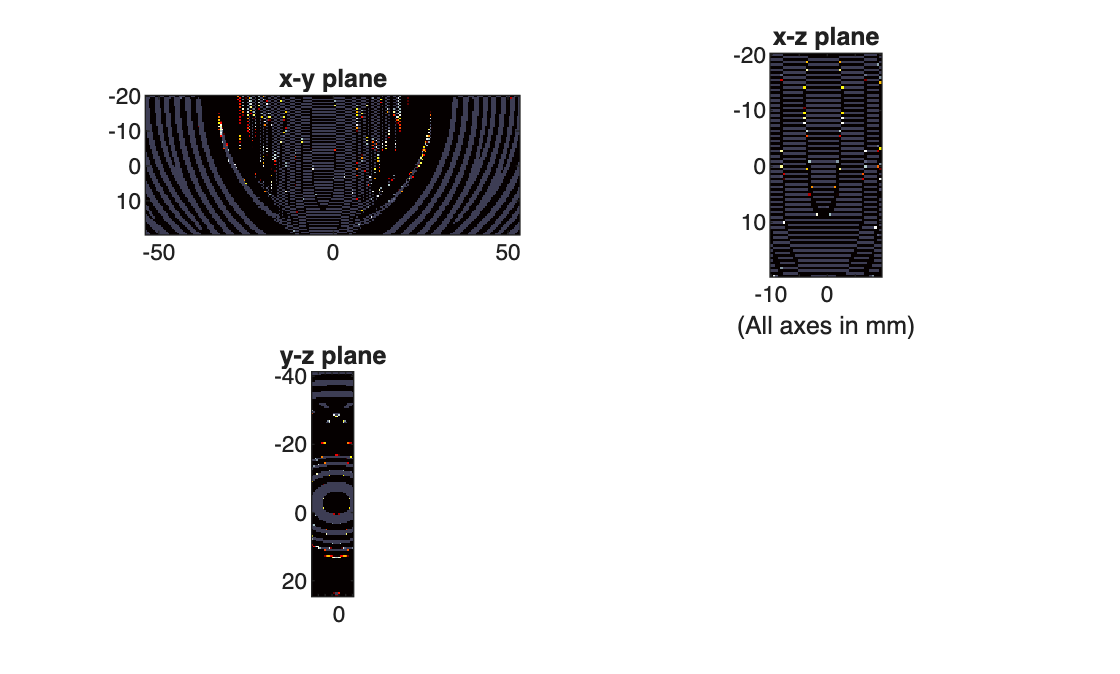

% SENSOR
input_args = { ...
    'PMLInside', false, ...
    'PMLSize', ...
    [PML_X_SIZE PML_Y_SIZE PML_Z_SIZE], ...
    'PlotPML', false, ...
    'DataCast', 'single', ...
    'DataRecast', true};


% MATRIZ PARA GUARDAR LAS SCAN LINES
% Cada fila será una scan line correspondiente a un ángulo.
% scan_lines(angle_index, time)

scan_lines = zeros( ...
    number_scan_lines, ...
    length(kgrid.t_array));


%% =========================================================
% 18. SIMULACIÓN DE LAS SCAN LINES
% ==========================================================
% Para cada steering angle:
%
% 1. cambia la dirección del haz
% 2. el transductor transmite
% 3. la onda se propaga por el medio
% 4. se generan ecos
% 5. el mismo transductor recibe
% 6. obtenemos RF multicanal
% 7. se aplica receive beamforming
% 8. obtenemos una scan line

for angle_index = 1:number_scan_lines

    %% -----------------------------------------------------
    % Actualizar steering angle
    % ------------------------------------------------------

    transducer.steering_angle = ...
        steering_angles(angle_index);


    %% -----------------------------------------------------
    % Ejecutar propagación
    % ------------------------------------------------------
    %
    % Orden de k-Wave:
    %
    % kgrid
    % medium
    % source
    % sensor
    %
    % Aquí:
    %
    % source = transducer
    % sensor = transducer

    sensor_data = kspaceFirstOrder3D( ...
        kgrid, ...
        medium, ...
        transducer, ...
        transducer, ...
        input_args{:});


    %% -----------------------------------------------------
    % Receive beamforming
    % ------------------------------------------------------
    %
    % sensor_data:
    % RF de cada uno de los 64 elementos
    %
    % transducer.scan_line:
    % aplica delays + apodización + suma
    %
    % resultado:
    % una única scan line

    scan_lines(angle_index,:) = ...
        transducer.scan_line(sensor_data);

end

% VISUALIZAR RF BEAMFORMADA
% Cada fila corresponde a una scan line obtenida con
% un steering angle distinto.
figure;
imagesc( ...
    kgrid.t_array*1e6, ...
    steering_angles, ...
    scan_lines);

xlabel('Time [\mus]');
ylabel('Steering angle [deg]');

title('Beamformed RF Scan Lines');
colorbar;


% ENVELOPE DETECTION
% La RF oscila positiva y negativamente.
% La envolvente permite obtener la magnitud del eco.
scan_lines_env = abs( ...
    hilbert(scan_lines.').');


% NORMALIZACIÓN
scan_lines_env = scan_lines_env ./ max(scan_lines_env(:));


% LOG COMPRESSION: permite visualizar ecos fuertes y débiles al mismo tiempo. 
% Se convierte la amplitud a escala de decibelios.
dynamic_range = 60;      % [dB]
scan_lines_bmode = ...
    20*log10(scan_lines_env + eps);

scan_lines_bmode( ...
    scan_lines_bmode < -dynamic_range) = ...
    -dynamic_range;

image_size = [ ...
    Nx*dx, ...
    Ny*dy];

%Scan conversion: esto es lo que ya nos da el ejemplo para plotear
b_mode = scanConversion( ...
    scan_lines_bmode, ...
    steering_angles, ...
    image_size, ...
    c0, ...
    kgrid.dt);


% VISUALIZAR B-MODE
figure;
imagesc(b_mode);
axis image;
colormap(gray);
colorbar;
title('Phased Array B-mode Image');

### Definimos el medium scaterring

Una imagen de ultrasonido no aparece simplemente porque exista tejido. El contraste aparece cuando la onda encuentra **cambios en las propiedades acústicas** del medio. 

Una de las propiedades más importantes es la impedancia acústica:Z=ρc

donde: ρ = densidad  y c = velocidad del sonido 

Si una onda pasa de una región con una impedancia a otra diferente, parte de la energía se transmite y parte se refleja. Por eso estructuras diferentes pueden aparecer con diferente brillo en B-mode. 

En este ejemplo, k-Wave no modela literalmente cada célula, sino que hace una aproximación numérica:

modifica ligeramente `sound_speed` y `density` en cada punto de la malla usando ruido gaussiano aleatorio.

Aplicamos esto  de antes y ploteamos el phantom y las inclusiones

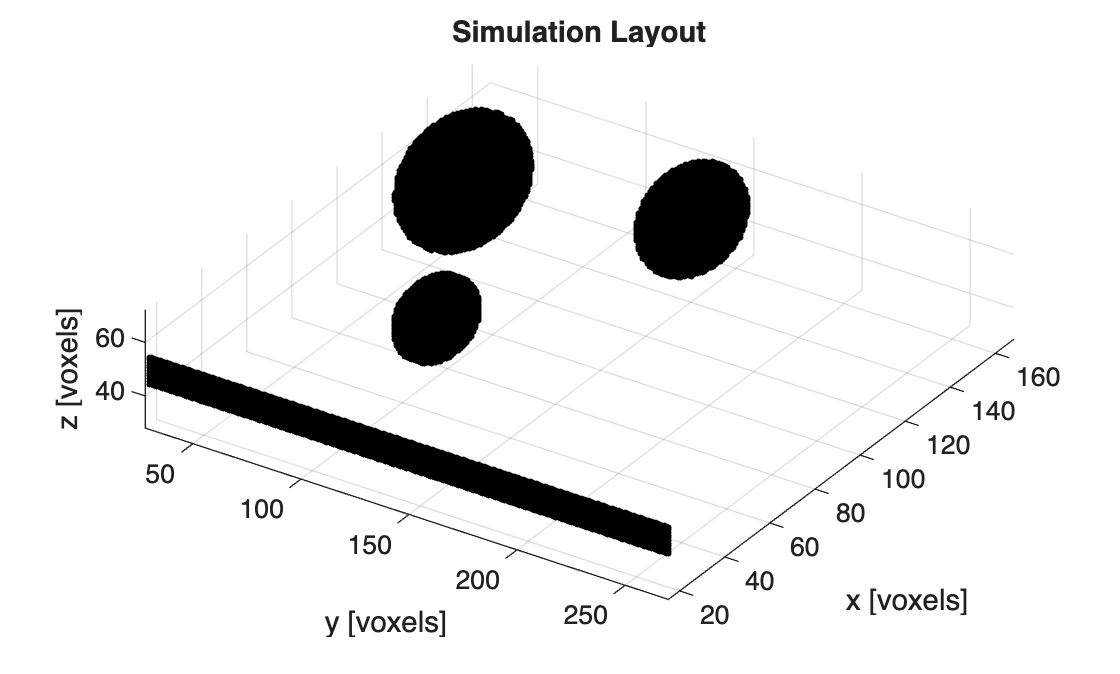

%Entonces el proceso es analogo
clear all;
close all;
clc;

Nx = 200;
Ny = 300;
Nz = 100;

dx = 0.2e-3;
dy = 0.2e-3;
dz = 0.2e-3;

kgrid = kWaveGrid(Nx,dx,Ny,dy,Nz,dz);

c0   = 1540;
rho0 = 1000;

rng(1);

scatter_strength = 0.005;

%Ruido gausiano anadido
sound_speed_map = ...
    c0 .* (1 + scatter_strength .* randn(Nx,Ny,Nz));

density_map = ...
    rho0 .* (1 + scatter_strength .* randn(Nx,Ny,Nz));

%% =========================================================
% 3. TRES ESFERAS
% ==========================================================
% makeBall:
% (Nx, Ny, Nz, x_pos, y_pos, z_pos, radius)
%
% x -> profundidad
% y -> posición horizontal
% z -> elevación
% radio -> grid points

% esfera grande izquierda
ball1 = makeBall( ...
    Nx,Ny,Nz, ...
    135, ...             % x = 27 mm profundidad
    50, ...              % y = 10 mm lateral
    round(Nz/2), ...
    22);                 % radio = 4.4 mm

% esfera pequeña superior
ball2 = makeBall( ...
    Nx,Ny,Nz, ...
    75, ...              % x = 15 mm profundidad
    100, ...             % y = 20 mm lateral
    round(Nz/2), ...
    14);                 % radio = 2.8 mm

% esfera inferior derecha
ball3 = makeBall( ...
    Nx,Ny,Nz, ...
    150, ...             % x = 30 mm profundidad
    140, ...             % y = 28 mm lateral
    round(Nz/2), ...
    18);                 % radio = 3.6 mm

balls = ball1 | ball2 | ball3;

% Anadimos mayor contraste a las esferas ya que poseen diferente propiedad
sound_speed_map(balls) = ...
    1600 .* (1 + 0.1 .* randn(nnz(balls),1));

density_map(balls) = ...
    1100 .* (1 + 0.1 .* randn(nnz(balls),1));

% TRANSDUCTOR SIMPLIFICADO PARA MOSTRAR EL LAYOUT
transducer_mask = zeros(Nx,Ny,Nz);
x_transducer = 15;
transducer_mask( ...
    x_transducer, ...
    30:270, ...
    45:55) = 1;

% plot
figure;
hold on;

% transductor
[xT,yT,zT] = ind2sub( ...
    size(transducer_mask), ...
    find(transducer_mask));

scatter3( ...
    yT, ...
    xT, ...
    zT, ...
    5, ...
    'k', ...
    'filled');

% esferas
[xB,yB,zB] = ind2sub( ...
    size(balls), ...
    find(balls));

scatter3( ...
    yB, ...
    xB, ...
    zB, ...
    5, ...
    'k', ...
    'filled');

xlabel('y [voxels]');
ylabel('x [voxels]');
zlabel('z [voxels]');

title('Simulation Layout');

axis tight;
grid on;
view(35,25);

**Imagen superior: layout 3D de la simulación**

Esta figura muestra la **geometría tridimensional completa** del experimento antes de simular.

Se representan:

- el transductor lineal como una barra negra; 

- las tres inclusiones esféricas dentro del volumen; 

- los ejes `x`, `y`, `z` en voxels.

Aqui se muestra la posición relativa del transductor y de las tres regiones esféricas incluidas en el scattering phantom. Las esferas representan heterogeneidades macroscópicas con propiedades acústicas diferentes al medio de fondo. Esta visualización sirve como comprobación geométrica del setup antes de ejecutar la simulación.

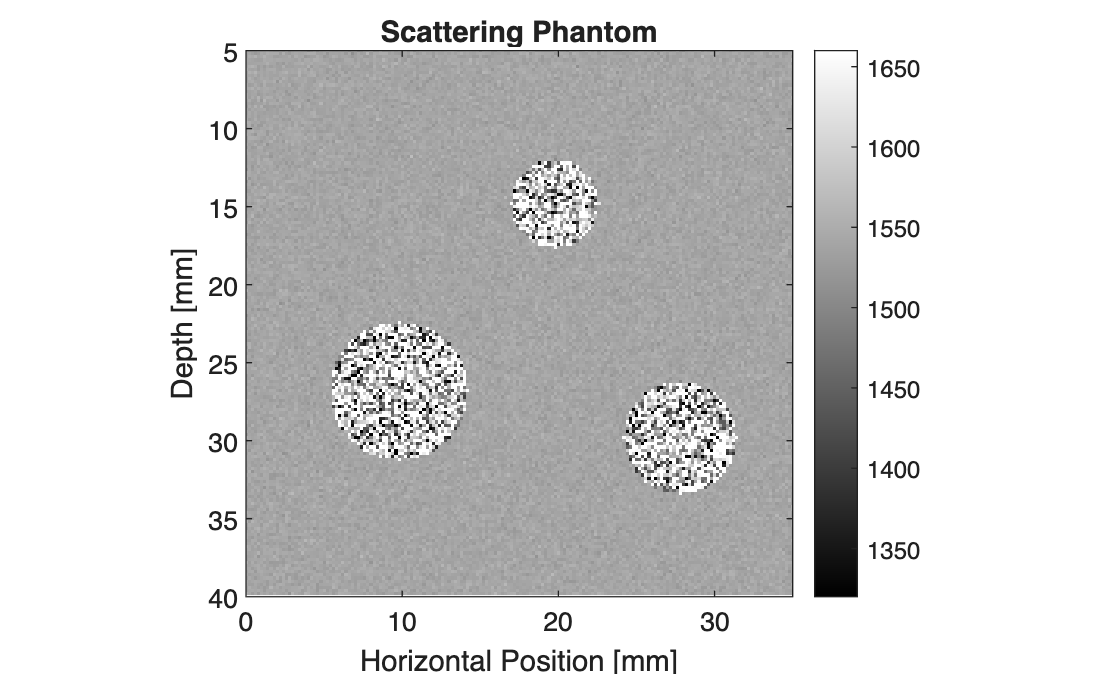

%% =========================================================
% 7. CORTE CENTRAL DEL SCATTERING PHANTOM
% ==========================================================

z_slice = round(Nz/2);

phantom_slice = ...
    squeeze(sound_speed_map(:,:,z_slice));

depth_axis = (0:Nx-1) * dx * 1e3;   % [mm]
horizontal_axis = (0:Ny-1) * dy * 1e3;

figure;

imagesc( ...
    horizontal_axis, ...
    depth_axis, ...
    phantom_slice);

axis image;
colormap(gray);

xlabel('Horizontal Position [mm]');
ylabel('Depth [mm]');

xlim([0 35]);
ylim([5 40]);

title('Scattering Phantom');

clim([1320 1660]); %ajusta la escala

colorbar;

**Corte del scattering phantom:** se muestra una sección 2D del volumen acústico en el plano del haz. La textura granular del fondo corresponde a pequeñas variaciones aleatorias de velocidad del sonido y densidad utilizadas para representar heterogeneidades microscópicas del tejido. Las tres regiones circulares corresponden al corte de las inclusiones esféricas 3D y presentan mayor scattering e impedancia, simulando heterogeneidades macroscópicas.

### Processing steps

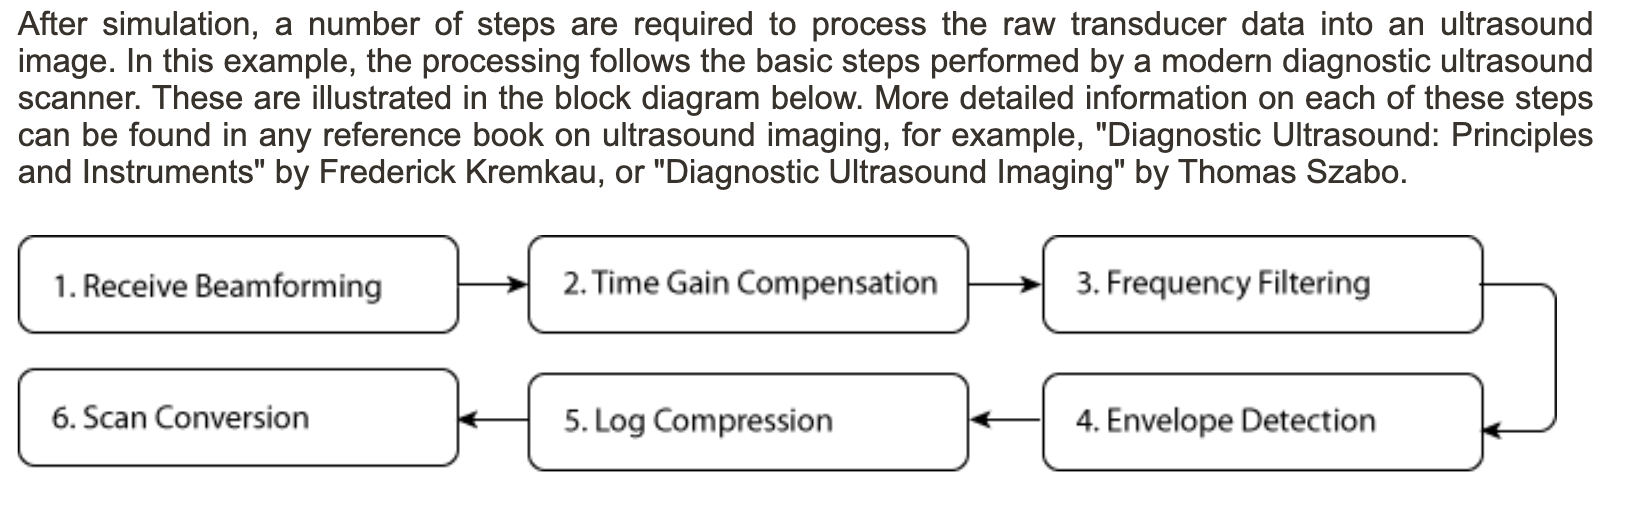

La imagen de **Processing Steps** resume cómo pasas de las señales RF crudas a una imagen B-mode interpretable. 

**1. Receive Beamforming**

Primero tienes la **RF recibida por los elementos del transductor**. Es una señal oscilatoria de alta frecuencia y todavía contiene toda la información temporal cruda de los ecos. The beamforming delays and weights are automatically calculated based on the transducer focus distance and apodization settings.

% extract the scan line from the sensor data

scan_lines(scan_line_index, :) = transducer.scan_line(sensor_data);

Antes del beamforming, es necesairo eliminar la senal de entrada del sensor grabado, pues k-Wave allows the transducer elements to both send and receive at the same time.

**2. Time Gain Compensation**

The acoustic waves generated by the ultrasound transducer lose energy as they propagate through the tissue due to acoustic attenuation (absorption and scattering) and focussing effects. Entonces, los ecos reflejados pueden aparecer pequenos y es necesario compensarlo con una correcion asumiendo que la relacion es:

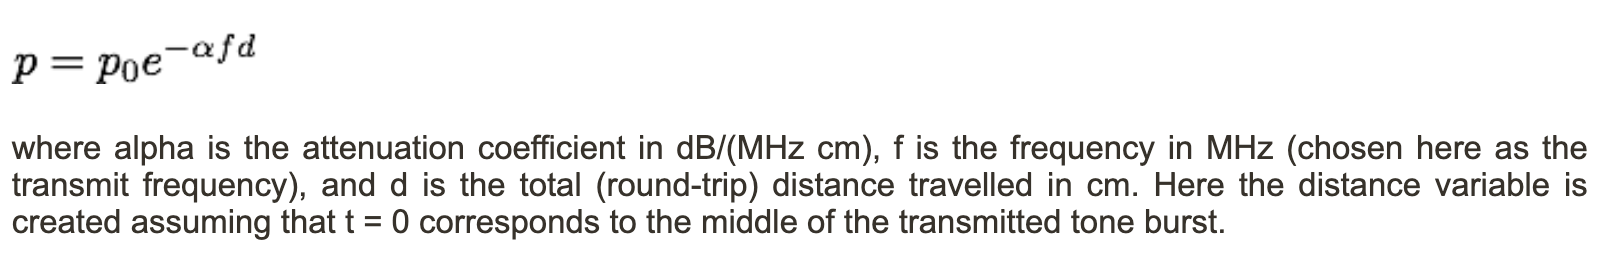

% create radius variable assuming that t0 corresponds to the middle of the

Unrecognized function or variable 'sensor_data'.

% input signal
t0 = length(input_signal) * kgrid.dt / 2;
r = c0 * ( (1:length(kgrid.t_array)) * kgrid.dt / 2 - t0);    % [m]

% define absorption value and convert to correct units
tgc_alpha_db_cm = medium.alpha_coeff * (tone_burst_freq * 1e-6)^medium.alpha_power;
tgc_alpha_np_m = tgc_alpha_db_cm / 8.686 * 100;

% create time gain compensation function based on attenuation value and
% round trip distance
tgc = exp(tgc_alpha_np_m * 2 * r);

% apply the time gain compensation to each of the scan lines
scan_lines = bsxfun(@times, tgc, scan_lines);

**3. Frequency Filtering**

The scan lines are then filtered using a Gaussian filter centered about the transmit frequency or the second harmonic. La idea es separar la imagen fundamental de la harmonic imaging y reducir componentes no deseadas.

% filter the scan lines using both the transmit frequency and the second harmonic
scan_lines_fund = gaussianFilter(scan_lines, 1/kgrid.dt, tone_burst_freq, 100, true);
scan_lines_harm = gaussianFilter(scan_lines, 1/kgrid.dt, 2 * tone_burst_freq, 30, true);

**4. Envelop Detection**

The high frequency variations in the scan lines are then removed in a demodulation process known as envelope detection. Here, this is achieved using [`envelopeDetection`](https://www.k-wave.org/documentation/envelopeDetection.php) which extracts the signal envelope using the Hilbert transform. La idea es convertir “ondas RF” en una señal de intensidad más fácil de representar como brillo.

% envelope detection
scan_lines_fund = envelopeDetection(scan_lines_fund);
scan_lines_harm = envelopeDetection(scan_lines_harm);

**5. Log Compression**

 To reduce this dynamic range, the scan lines are log compressed using [`logCompression`](https://www.k-wave.org/documentation/logCompression.php) with a normalised compression ratio of 3. La compresión logarítmica reduce ese rango para que ecos fuertes y débiles puedan visualizarse simultáneamente en escala de grises.

% normalised log compression
compression_ratio = 3;
scan_lines_fund = logCompression(scan_lines_fund, compression_ratio, true);
scan_lines_harm = logCompression(scan_lines_harm, compression_ratio, true);

**6. Scan Conversion**

Las scan lines procesadas se reorganizan espacialmente para construir la imagen final, es decir pasar de muchas líneas 1D a una imagen 2D B-mode.

% upsample the image using linear interpolation
scale_factor = 2;
scan_lines_fund = interp2(1:kgrid.Nt, (1:number_scan_lines).', scan_lines_fund, 1:kgrid.Nt, (1:1/scale_factor:number_scan_lines).');
scan_lines_harm = interp2(1:kgrid.Nt, (1:number_scan_lines).', scan_lines_harm, 1:kgrid.Nt, (1:1/scale_factor:number_scan_lines).');

clear all

%% CARGAR DATOS RF YA SIMULADOS
load('example_us_bmode_scan_lines.mat');

%% VER QUÉ VARIABLES CONTIENE este tipo de scan lines
whos

%% ENVELOPE DETECTION
scan_lines_env = abs(hilbert(scan_lines.').');

%% NORMALIZAR
scan_lines_env = ...
    scan_lines_env ./ max(scan_lines_env(:));

%% LOG COMPRESSION
dynamic_range = 60;   % [dB]

  Name             Size                Bytes  Class     Attributes

  scan_lines      96x1585            1217280  double              



bmode = 20*log10(scan_lines_env + eps);
bmode(bmode < -dynamic_range) = -dynamic_range;

%% VISUALIZAR
figure;
imagesc(bmode.');
colormap(gray);
colorbar;
xlabel('Scan line');
ylabel('Depth sample');
title('B-mode Image');

Imagen B mode sin filtros ni compoensacion alguna, ahora se realizara con el procedimiento que se dijo:

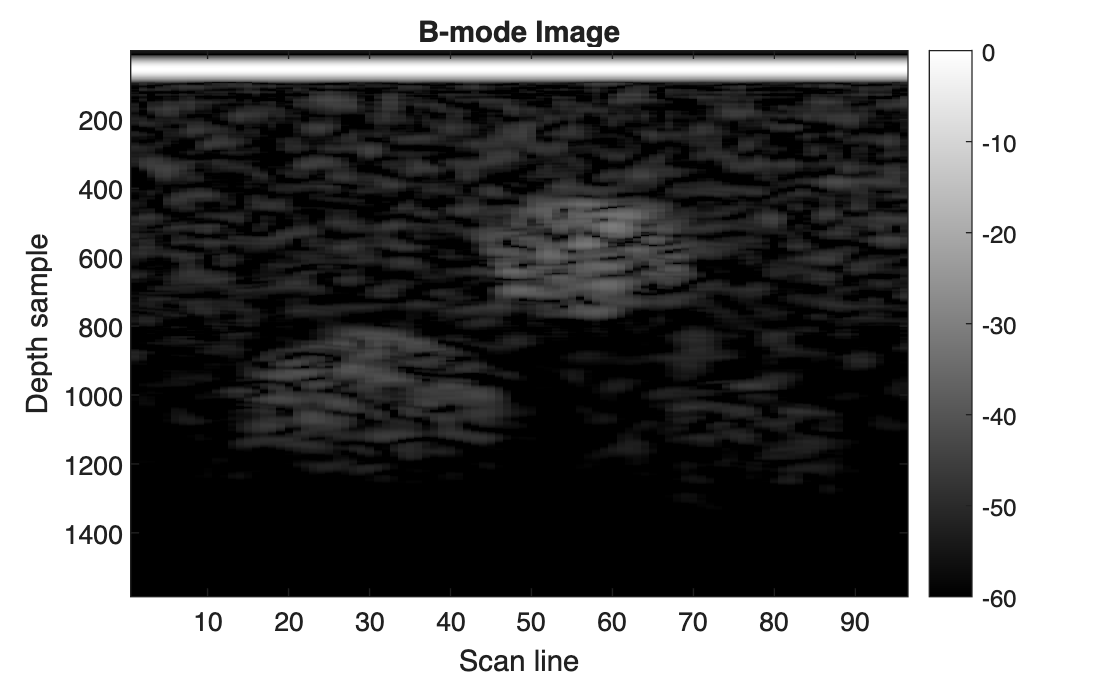

clear all;
close all;
clc;

%% =========================================================
% 1. CARGAR SCAN LINES YA SIMULADAS
% ==========================================================

load('example_us_bmode_scan_lines.mat');


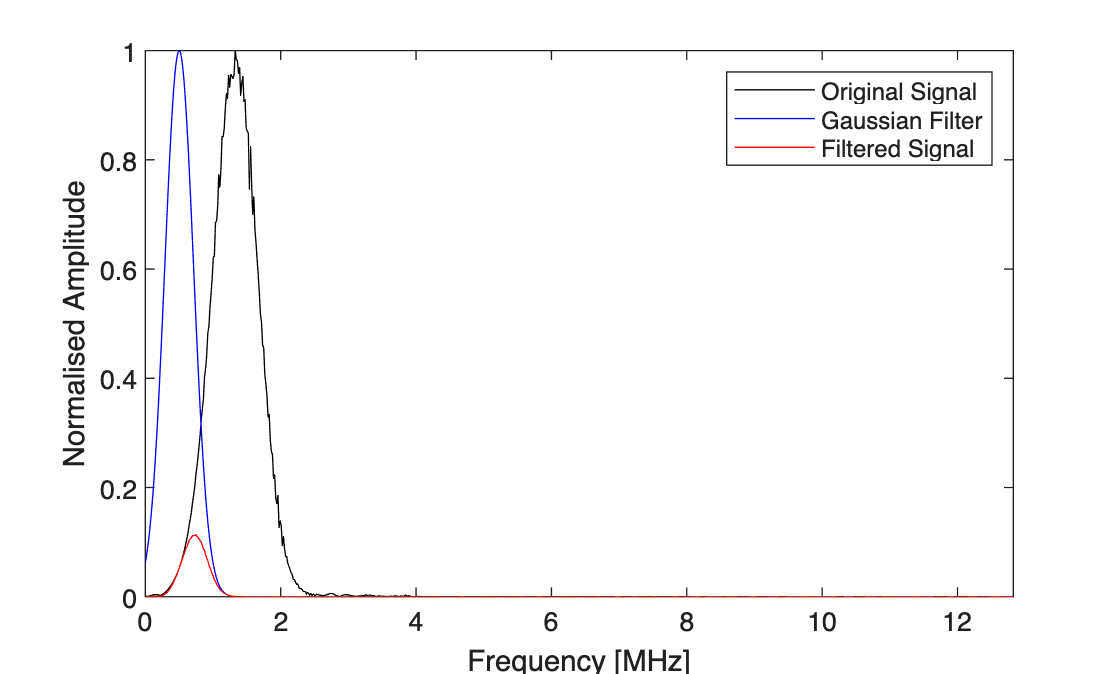

% scan_lines:
% filas    = scan lines
% columnas = muestras temporales

number_scan_lines = size(scan_lines,1);
Nt = size(scan_lines,2);


%% =========================================================
% 2. PARÁMETROS
% ==========================================================

c0 = 1540;                  % [m/s]

tone_burst_freq   = 0.5e6;  % [Hz]
tone_burst_cycles = 5;

medium.alpha_coeff = 0.75;
medium.alpha_power = 1.5;


%% =========================================================
% 3. RECONSTRUIR KGRID Y TIEMPO
% ==========================================================

Nx = 200;
Ny = 300;
Nz = 100;

dx = 0.2e-3;
dy = 0.2e-3;
dz = 0.2e-3;

kgrid = kWaveGrid( ...
    Nx,dx, ...
    Ny,dy, ...
    Nz,dz);

t_end = 45e-6;

kgrid.t_array = makeTime( ...
    kgrid, ...
    c0, ...
    [], ...
    t_end);


%% =========================================================
% 4. INPUT SIGNAL
% ==========================================================
% Pulso transmitido; se usa para calcular la referencia temporal.

input_signal = toneBurst( ...
    1/kgrid.dt, ...
    tone_burst_freq, ...
    tone_burst_cycles);


%% =========================================================
% 5. TIME GAIN COMPENSATION
% ==========================================================
% Compensa la pérdida de amplitud con la profundidad.
t0 = length(input_signal) * kgrid.dt / 2;

r = c0 * ( ...
    (1:Nt) * kgrid.dt / 2 ...
    - t0);

tgc_alpha_db_cm = ...
    medium.alpha_coeff * ...
    (tone_burst_freq * 1e-6)^medium.alpha_power;

tgc_alpha_np_m = ...
    tgc_alpha_db_cm / 8.686 * 100;

tgc = exp( ...
    tgc_alpha_np_m * 2 .* r);

scan_lines_tgc = bsxfun( ...
    @times, ...
    scan_lines, ...
    tgc);


%% =========================================================
% 6. FREQUENCY FILTERING
% ==========================================================
% Fundamental f0 y segunda armónica 2f0.
scan_lines_fund = gaussianFilter( ...
    scan_lines_tgc, ...
    1/kgrid.dt, ...
    tone_burst_freq, ...
    100, ...
    true);

scan_lines_harm = gaussianFilter( ...
    scan_lines_tgc, ...
    1/kgrid.dt, ...
    2*tone_burst_freq, ...
    30, ...
    true);

[Example: Simulating B-mode Images Using A Phased Array](https://www.k-wave.org/documentation/example_us_bmode_phased_array.php)

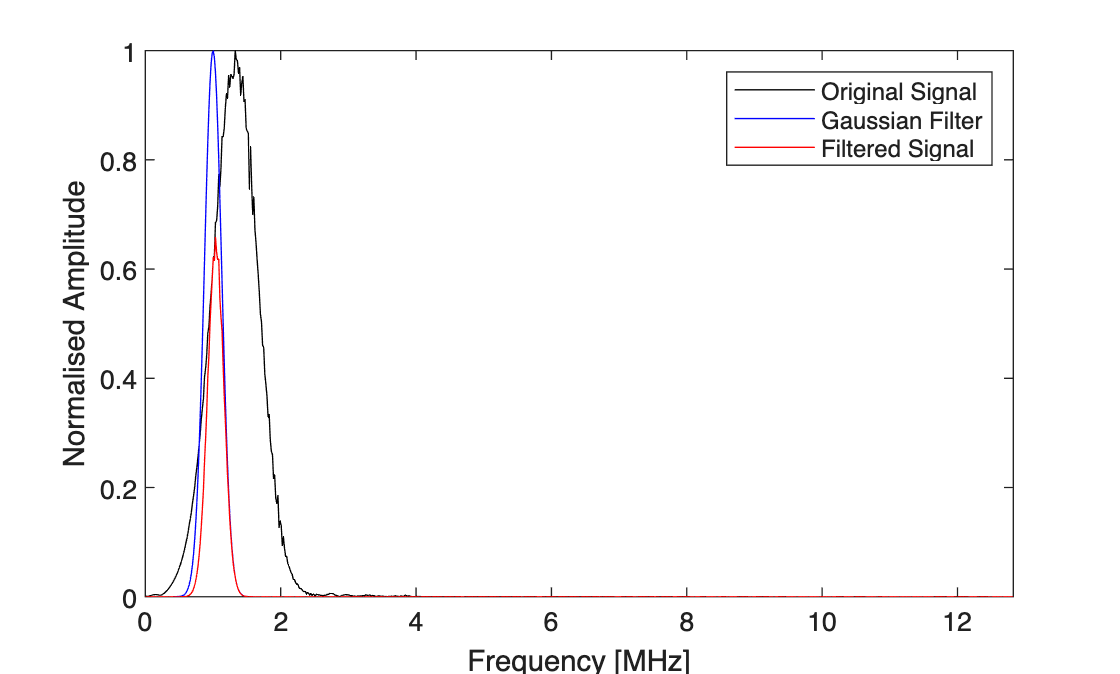

% loop through the range of angles to test
for angle_index = 1:number_scan_lines

    % update the current steering angle
    transducer.steering_angle = steering_angles(angle_index);

    % run the simulation

    sensor_data = kspaceFirstOrder3D(kgrid, medium, transducer, transducer, input_args{:});

    % extract the scan line from the sensor data
    scan_lines(angle_index, :) = transducer.scan_line(sensor_data);

end

% set the desired size of the image
image_size = [Nx * dx, Ny * dy];

% convert the data from polar coordinates to Cartesian coordinates for
% display
b_mode_fund = scanConversion(scan_lines_fund, steering_angles, image_size, c0, kgrid.dt);
b_mode_harm = scanConversion(scan_lines_harm, steering_angles, image_size, c0, kgrid.dt);

Undefined variable 'input_args'.